**二维绘图命令——plot**

x = linspace(0, 2*pi, 100);
y = sin(x);

y2 = cos(x);

plot(x, y, x, y2);

% 设置坐标轴标签
xlabel('x');
ylabel('y');

title('y=sinx y=cosx');

% 图例
legend('y=sin(x)', 'y=cos(x)'); % 顺序要保持一致

**绘制子图——subplot**

subplot(1, 2, 1);
plot(x, y);
title('sin');
subplot(1, 2, 2);
plot(x, y2);
title('cos');

**分块图——tiledlayout**

t = tiledlayout(1, 2);
title(t, 'demo');

x = linspace(-5, 5);

nexttile(t);
y = x.^2;
plot(x, y);
title('y = x^2');

nexttile(t);
y = sin(x);
plot(x, sin(x));
title('y = sin(x)');

**绘图修饰**

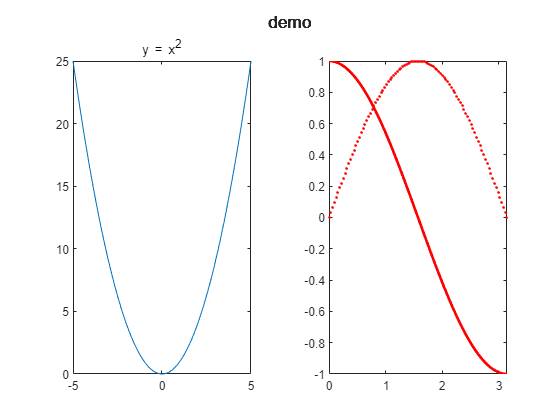

x = linspace(0, pi);
plot(x, sin(x), 'r.');
hold on;
plot(x, cos(x), 'r-', ...
	'lineWidth', 2);